# Cross-Correlation

In signal processing, *cross-correlation* is a measure of similarity of two series as a function of the displacement of one relative to the other. It's commonly used for searching a long signal for a shorter, known feature.

The cross-correlation is similar in nature to the convolution of two functions. In an autocorrelation, which is the cross-correlation of a signal itself, there will always be a peak at a lag of zero, and its size will be the signal energy.

## I- Measuring Signal Similarities

This example shows how to measure signal similarities. It will be help you answer questions such as : How do I compare signals with different lengths or different sampling rates ? How do I find if there is a signal or just noise in measurement ? Are two signals related ? How to measure a delay between two signals (and How do I align them) ? How do I compare the frequency content of two signals ? Similarities can also be found in different sections of a signal to determine if the signal is periodic or not.

## **II- Example of *****cross-correlation *****between sinusPulse and its noisy version :**

load ToneParameters.mat

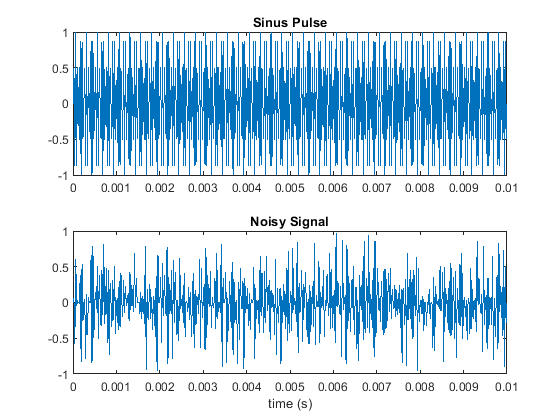

t_sinusPulse = (0:length(sinusPulse)-1)/samplingFrequency;          % time vector of sinusPulse
t_noisySignal = (0:length(noisy_Signal)-1)/samplingFrequency;        % time vector of noisySignal

subplot(2,1,1)
plot(t_sinusPulse,sinusPulse)
title('Sinus Pulse')

subplot(2,1,2)
plot(t_noisySignal,noisy_Signal)
title('Noisy Signal')
xlabel('time (s)')

Plotting the *cross-correlation.*

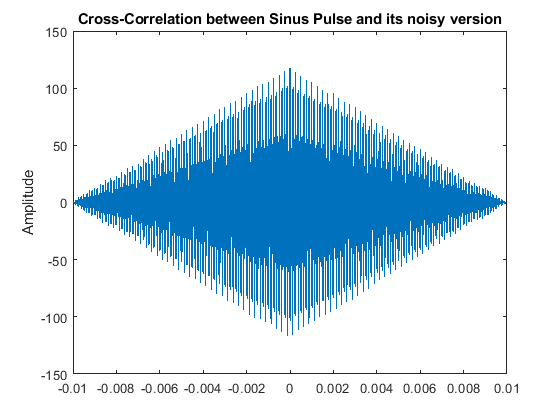

[acor, lag] = xcorr(sinusPulse,noisy_Signal);
figure
plot(lag/samplingFrequency,acor)
ylabel('Amplitude')
title('Cross-Correlation between Sinus Pulse and its noisy version')

## III- **Example of *****cross-correlation***** between Linear FM waveform and its noisy version :**

load FM_WaveformParameters.mat

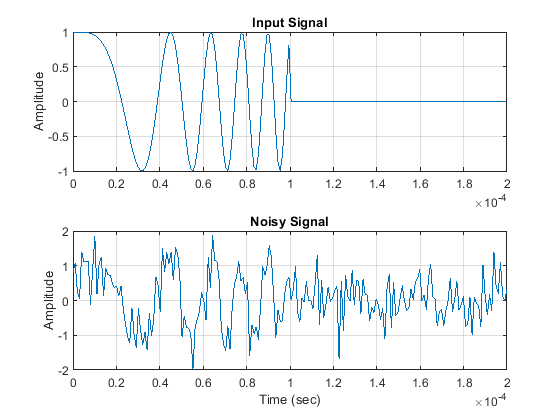


t = linspace(0,numel(inputSignal)/waveform.SampleRate,...    %% Time Vector
    waveform.SampleRate/waveform.PRF);              
subplot(2,1,1)                                       % Split the windowplot in 2 windows    
plot(t,real(inputSignal))
title('Input Signal')
xlim([0 max(t)])
grid on
ylabel('Amplitude')
subplot(2,1,2)
plot(t,real(noisySignal))
title('Noisy Signal')
xlim([0 max(t)])
grid on
xlabel('Time (sec)')
ylabel('Amplitude')

Plotting the *cross-correlation.*

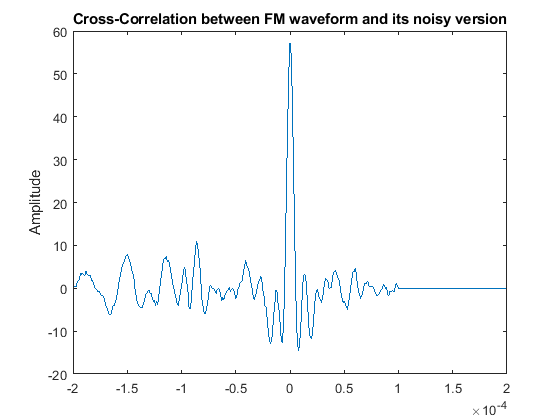

[acor1, lag1] = xcorr(real(inputSignal),real(noisySignal));
figure
plot(lag1/waveform.SampleRate,real(acor1))
ylabel('Amplitude')
title('Cross-Correlation between FM waveform and its noisy version')

#### References :

- [https://www.youtube.com/watch?v=RO8s1TrElEw](https://www.youtube.com/watch?v=RO8s1TrElEw)

- [https://en.wikipedia.org/wiki/Cross-correlation](https://en.wikipedia.org/wiki/Cross-correlation)

- [https://www.mathworks.com/help/signal/ref/xcorr.html](https://www.mathworks.com/help/signal/ref/xcorr.html)

- [https://www.mathworks.com/help/signal/examples/measuring-signal-similarities.html](https://www.mathworks.com/help/signal/examples/measuring-signal-similarities.html)